# Sensitivity on Km and Vmax in predicted growth and comparison with experimental data

This live script runs a comets simulation mimicing the environmnet used in wet lab experiments with *Prochlorococcus marins *MED4. The experimental data is from David Shear's lab, more precisely from Grossowic et al., 2017.

Using regular FBA we have idenitfied possible combinations of Km and Vmax that matches the observed initial gross growth rate of 0.5 / d. Taking into account the death rate of 0.1 / d we get a net growth rate of 0.4 /d. 

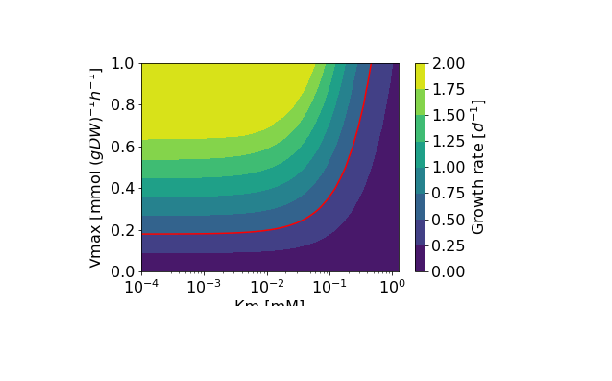

I = imread("Km_Vmax_match.png");
imshow(I)

% Read Km Vmax values
KmVmax = readtable('km_vmax05.csv');
KmArr = KmVmax.Km(19:4:end);
VmaxArr = KmVmax.Vmax(19:4:end);

% Init cobra toolbox
initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.23.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)...usage: git submodule [--quiet] [--cached]
   or: git submodule [--quiet] add [-b <branch>] [-f|--force] [--name <name>] [--reference <repository>] [--] <repository>

 Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi811\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...gurobi
ibm_cplex
tomlab_cplex
glpk
mosek
matlab
pdco
quadMinos
dqqMinos
cplex_direct
cplexlp
qpng
tomlab_snopt
lp_solve
 Done.
 > Setting default solvers ... 

% Load Prochlorococcus Genome-scale model
model_fn = '..\..\Model_files\iSO595v6.xml';
model = readCbModel(model_fn);

timeStep = 0.1;%
folder = [pwd '\kmVmaxComets5'];

### Define model light settings

In the following we assume that the light source is monochromatic at 680nm, however it is possible to extend the following calculations to a wave-length dependent light-source.  

It is necessary to calculate a model-specific weight-specific absorption rate, this is achieved by using  the derived pigment absorption spectra provided by Bricaud et al., 2004. The calculations follows the methods in Bricaud et al., 2004, as originally described in Moreal and Bricaud, 1981. 

#### Define variables such as pigment concentrations in *Prochlorococcus, *absorption coefficients and refraction index  

At 680nm we can ignore absorption by other pigments than divinyl chlorophyll a and b.

% The ratio of chlorophyll is extracted from the model biomass-function
ci_dvchla = 0.028*0.581196581 % g / gDW (Partensky 1993 / Casey 2016)

ci_dvchla = 0.0163

ci_dvchlb = 0.028*0.047008547 % g / gDW (Partensky 1993 / Casey 2016)

ci_dvchlb = 0.0013

absorption_dvchla_680 = 0.018358; % m2 mg-1 (Bricaud et al., 2004)
absorption_dvchlb_680 = 0.0018;   % m2 mg-1 (Bricaud et al., 2004)
absorption_water_680 = 0.465; % m^-1 (Pope and Fry, 1997)
wavelength = 680;% nm
diameter = 0.6; % um 
n_dash = 13.77*1e-3; % imaginary part of refractive index at 67 nm, from Stramski et al
lightFlux = 0.02; % mmol Q / m^2 / s (used in Grossowicz et al., 2017)
%lightFlux = 0.1;
%lightFlux = 10000

#### Calculate the packaging effect

This is taking into account that the light-aborsbing pigments are not dissolved in the media, but contained with in discrete cells. See Moreail and Bricaud, 1981, for a thorough explanation. 

% Calculate the packaging effect index Q* 
size_parameter_alpha = diameter*1e3*pi/wavelength;
rho_dash = 4*size_parameter_alpha*n_dash;
Q_a = 1+(2*exp(-rho_dash)/rho_dash)+2*(exp(-rho_dash)-1)/rho_dash^2;
packaging_effect = 1.5*Q_a/rho_dash;

#### Calculate the weight-specific absorption coefficient 

% This coefficient is in units m^2/ g DW biomass
% Multiply by 1e3 to convert from g to mg
absorption_biomass = packaging_effect*(ci_dvchla*1e3*absorption_dvchla_680+ci_dvchlb*1e3*absorption_dvchlb_680);


#### Set the calculated absorption rate as a model parameter for the exchange reaction of light

absorption_matrix = zeros(1,2);
absorption_matrix(1) = absorption_water_680;
absorption_matrix(2) = absorption_biomass;
model  = setLight(model, {'LightEX'}, absorption_matrix);

% Initial population in Grossowizc is 1.3e9 cells/L
grid_size = 1; %cm
grid_volume_cm3 = grid_size^3; %Cubic centimeters
grid_volume = grid_volume_cm3*1e-3; % Convert from cubic centimeters to L
cell_weight = 66*1e-15;  % g per cell (Cermak et al., 2017)
initial_pop = 1.3e9*cell_weight*grid_volume;
for i=1:length(KmArr)
    % Define filenames
    folder_i = [folder '\' num2str(i)];
    if ~exist(folder_i,'dir')
        mkdir(folder_i);
    end
    
    fluxLogfn = sprintf('fluxLog_%d.csv',i);
    biomassLogfn = sprintf('biomassLog_%d.csv',i);
    mediaLogfn = sprintf('mediaLog_%d.csv',i);
    model.description = sprintf('iSO595_%d',i);
    layout_name = sprintf('layout_%d.txt',i);
    
    model = setVmax(model, 'AmmoniaEX', VmaxArr(i));% mmol/gDW/h
    model = setKm(model, 'AmmoniaEX', KmArr(i)*1e-3);% 0.01 mM, but mmol/cm^3 is used in
    model = setVmax(model, 'HCO3EXcar', 18.43);
    model = setKm(model, 'HCO3EXcar', 0.082*1e-3);
    model = setVmax(model, 'FAKEOrthophosphateEX', 0.7575);
    model = setKm(model, 'FAKEOrthophosphateEX', 0.00053*1e-3);
    
    % Creat layout
    layout = CometsLayout();
    layout = layout.addModel(model);
    
    layout = setInitialPop(layout, '1x1', initial_pop); % g DW
    
    % Set simulation parameters
    
    layout.params.mediaLogName = [folder_i '\' mediaLogfn];
    layout.params.writeMediaLog = true;
    layout.params.mediaLogRate = 10;
    layout.params.biomassLogName = [folder_i '\' biomassLogfn];
    layout.params.writeBiomassLog = true;
    layout.params.biomassLogRate = 10;
    
    % Write fluxes
    layout.params.fluxLogName =  [folder_i '\' fluxLogfn];
    layout.params.writeFluxLog = false;
    
    
    layout.params.maxCycles = 7000;
    layout.params.timeStep = timeStep; %Hours
    layout.params.spaceWidth = grid_size; % Centimeters (0.1 is default value)
    layout.params.maxSpaceBiomass = 100000;
    layout.params.defaultDiffConst = 0;
    layout.params.objectiveStyle = 'MAX_OBJECTIVE_MIN_TOTAL';
    layout.params.deathRate = 0.1/24; % Per hour. From Grossowicz (they reference William and Follows, 2011)
    %layout.params.defaultVmax = 1000;
    %layout.params.defaultKm = 0.0001;
    %put a timestep
    layout.params.useLogNameTimeStamp=false;
    layout.params.fluxLogFormat = 'COMETS';
    layout.params.mediaLogFormat = 'COMETS';
    layout.params.biomassLogFormat = 'COMETS';

### Define medium as PRO99, with modifications in Grossowicz, 2017

Defined in Moore et al., 2007. Here given in mmol whereas umol is used by Moore et al., 2007. 

PRO99 pH: 7.73 (Grossowicz, 2017) / pH Grossowicz: 7.83.

In Grossowicz, 1 mM Bicarbonate added at day 0, 5, 11, 18

    % Define medium in uM
    pro99_media = struct('ammonia', 100, ... % 800 in PRO99
                         'bicarbonate', 3000, ... % Somewhat less in PRO99
                         'phosphate', 50);
    
    % Calculate values in mmol and set to layout
    grid_volume = layout.params.spaceWidth^3*1e-3; % In cubic decimetermeter aka liters
    layout = layout.setMedia('Ammonia[e]', pro99_media.ammonia*1e-3*grid_volume); % in mmol
    layout = layout.setMedia('HCO3[e]', pro99_media.bicarbonate*1e-3*grid_volume); % in mmol
    layout = layout.setMedia('Orthophosphate[e]', pro99_media.phosphate*1e-3*grid_volume); % in mmol

### Define salts and mineral needed for growth

Set to maximum value to ensure these compounds are not limiting growth in any way

    %layout = layout.setMedia('HCO3[e]', 1000);
    %layout = layout.setMedia('CO2[e]', 1000);
    layout = layout.setMedia('H[e]', 1000);
    %layout = layout.setMedia('Orthophosphate[e]', 1000); 
    layout = layout.setMedia('H2O[e]', 1000);
    
    layout = layout.setMedia('Cadmium[e]', 1000);
    layout = layout.setMedia('Calcium_cation[e]', 1000);
    layout = layout.setMedia('Chloride_ion[e]', 1000);
    layout = layout.setMedia('Cobalt_ion[e]', 1000);
    layout = layout.setMedia('Copper[e]', 1000);
    
    layout = layout.setMedia('Fe2[e]', 1000);
    layout = layout.setMedia('Magnesium_cation[e]', 1000);
    layout = layout.setMedia('Molybdenum[e]', 1000);
    layout = layout.setMedia('K[e]', 1000);
    layout = layout.setMedia('Selenate[e]', 1000);
    layout = layout.setMedia('Sodium_cation[e]', 1000);
    layout = layout.setMedia('Strontium_cation[e]', 1000);
    layout = layout.setMedia('Sulfate[e]', 1000);
    layout = layout.setMedia('Zn2[e]', 1000);
    %layout = layout.setMedia('Hydrogen_sulfide[e]',1000);
    layout = layout.setGlobalStaticMedia('Photon[e]', lightFlux);
    
    % Write layout
    createCometsFiles(layout, folder_i, layout_name);
end

for i=1:length(KmArr)
    folder_i = [folder '\' num2str(i)];
    runCometsOnDirectory(folder_i);
end

cd('../..');

## Plot results

% Load experimental data

cell_data = readtable('data_set_1_xdot93212.csv');

cell_data.std = nanstd(cell_data{:, 2:end},0, 2);
cell_data.mean = nanmean(cell_data{:, 2:end}, 2);
ammonium_data = readtable('data_set_2_Nx.csv');

ammonium_data.mean = nanmean(ammonium_data{:, 2:end}, 2)*1e-3;% Converting from uM to mM
ammonium_data.std = nanstd(ammonium_data{:, 2:end}, 0, 2)*1e-3;

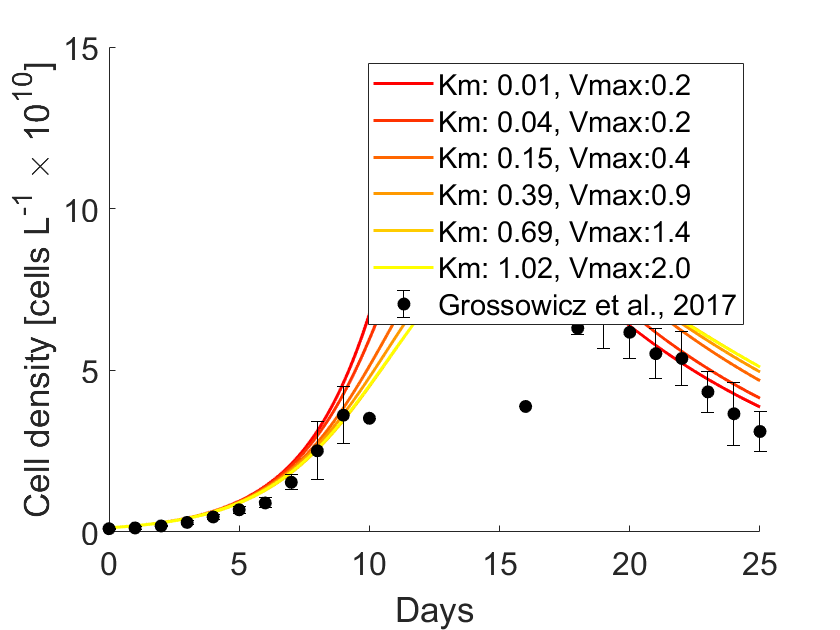

f1 = figure();
% Values in g/cell*1e-10
hold on;
c = colormap(autumn(11));
for i=1:2:11
    folder_i = [folder '\' num2str(i)];
    biomassLogfn = sprintf('biomassLog_%d.csv',i);
    biomass = parseBiomassLog([folder_i '\' biomassLogfn]);
    time_array = biomass.t*timeStep/24;
    %converting from biomass (g DW) to number of cells
    cell_weight = 66*1e-15;  % g per cell (Cermak et al., 2017)
    N_cells = biomass.biomass/cell_weight/grid_volume;
    name = sprintf('Km: %.2f, Vmax:%.1f', KmArr(i), VmaxArr(i));
    plot(time_array, N_cells*1e-10,'color',c(i,:), 'DisplayName', name, 'LineWidth',1.5);
end
errorbar(cell_data.xdot9312, cell_data.mean*1e-7, cell_data.std*1e-7, "vertical", 'o','MarkerFaceColor','k','Color','k', 'DisplayName','Grossowicz et al., 2017')
xlabel('Days', 'fontsize',18)
ylabel('Cell density [cells L^{-1} \times 10^{10}]', 'fontsize',18)
set(gca,'fontsize',16)
legend();
xlim([0, 25])
hold off;
saveas(f1,'growth','epsc')

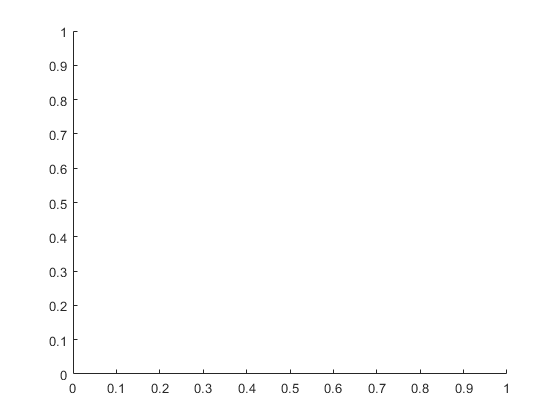

f2 = figure();
hold on;


for i=2:2:11
    folder_i = [folder '\' num2str(i)];
    mediaLogfn = sprintf('mediaLog_%d.csv',i);
    media = parseMediaLog([folder_i '\' mediaLogfn]);
    ammonia_table = media(strcmp('Ammonia[e]', media.metname),:);
    time_array = ammonia_table.t*timeStep/24;
    ammonia = ammonia_table.amt/grid_volume;% Convert from mmol to mM
    p = plot(time_array, ammonia, 'color',c(i,:), 'LineWidth',1.5);
end

Unrecognized function or variable 'c'.

errorbar(ammonium_data.Nx, ammonium_data.mean, ammonium_data.std, "vertical", 'o','MarkerFaceColor','k','Color','k', 'DisplayName','Measured growth');
xlabel('Days', 'fontsize',18);
ylabel('NH_{4}^{+} [mmol L^{-1}]','fontsize', 18);

set(gca,'fontsize',16)
xlim([0, 28])
ylim([0, 0.22])
saveas(f2,'ammonium','epsc')